2D Fourier Series to Structural Tensor

** Data Generation**

warning off
clear all
close all
clc
addpath(genpath('../..'));

theta_full = 1:1:360;
data_raw1 = [27 33 40 48 58 70 84 101 121 144 171 203 240 283 333 392 459 537 626 728 845 978 1129 1300 1494 1712 1957 2231 2538 2879 3258 3678 4142 4653 5213 5827 6496 7224 8014 8868 9788 10777 11836 12967 14170 15447 16796 18218 19710 21272 22900 24591 26341 28145 29998 31893 33822 35779 37755 39740 41726 43701 45655 47578 49458 51283 53044 54727 56324 57822 59211 60483 61628 62637 63505 64223 64788 65194 65439 65520 65439 65194 64788 64223 63505 62637 61628 60483 59211 57822 56324 54727 53044 51283 49458 47578 45655 43701 41726 39740 37755 35779 33822 31893 29998 28145 26341 24591 22900 21272 19710 18218 16796 15447 14170 12967 11836 10777 9788 8868 8014 7224 6496 5827 5213 4653 4142 3678 3258 2879 2538 2231 1957 1712 1494 1300 1129 978 845 728 626 537 459 392 334 283 240 203 171 144 121 101 84 70 58 48 40 33 27 22 18 15 12 10 8 7 6 5 4 3 4 5 6 7 8 10 12 15 18 22 27 33 40 48 58 70 84 101 121 144 171 203 240 283 334 392 459 537 626 728 845 978 1129 1300 1494 1712 1957 2231 2538 2879 3258 3678 4142 4653 5213 5827 6496 7224 8014 8868 9788 10777 11836 12967 14170 15447 16796 18218 19710 21272 22900 24591 26341 28145 29998 31893 33822 35779 37755 39740 41726 43701 45655 47578 49458 51283 53044 54727 56324 57822 59211 60483 61628 62637 63505 64223 64788 65194 65439 65520 65439 65194 64788 64223 63505 62637 61628 60483 59211 57822 56324 54727 53044 51283 49458 47578 45655 43701 41726 39740 37755 35779 33822 31893 29998 28145 26341 24591 22900 21272 19710 18218 16796 15447 14170 12967 11836 10777 9788 8868 8014 7224 6496 5827 5213 4653 4142 3678 3258 2879 2538 2231 1957 1712 1494 1300 1129 978 845 728 626 537 459 392 334 283 240 203 171 144 121 101 84 70 58 48 40 33 27 22 18 15 12 10 8 7 6 5 4 3 4 5 6 7 8 10 12 15 18 22];
data_raw2 = data_raw1;
data_raw2 = circshift(data_raw2',70)'/2.2;
data_raw = data_raw1 + data_raw2;
gamma = data_raw/sum(data_raw);


**Fourier Series fit**

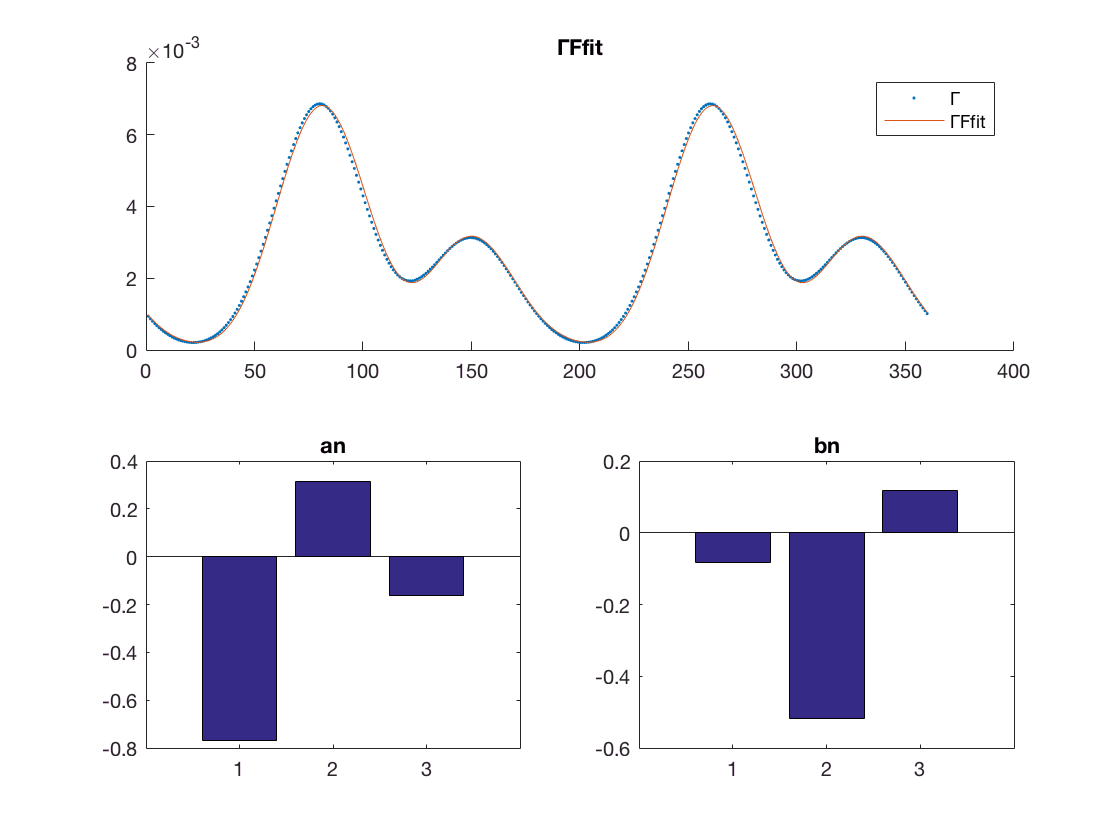

fs_order = 6;
an = [];
bn = [];
for n = 2:2:(fs_order)
   an = [an compute_an(n, gamma, 2:360)];
   bn = [bn compute_bn(n, gamma, 2:360)];
end

gamma_Ffit = evalFourier(an, bn, 1, 1:360);
gamma_Ffit=gamma_Ffit/sum(gamma_Ffit); %% This is weird

figure 
subplot(2,2,1:2) 
hold on
plot(1:360,gamma,'.') 
plot(1:360,gamma_Ffit)
legend('show','Γ','ΓFfit'); title('Fourier Series Fit');
hold off

title('ΓFfit'); 
subplot(2,2,3); bar(an); title('an');
subplot(2,2,4); bar(bn); title('bn');

**Inspection of STFit and θ derived from Dij**

D = GenerateTensors(an,bn);
gamma_STFit = evalGammaST(D,1:360);
gamma_STFit = gamma_STFit/sum(gamma_STFit);

D_ij = D{1};  
[v, d] = eig(D_ij);
theta1 = atan(v(2,1)/v(1,1)) * (180/pi) + 90;
theta2 = atan(v(2,2)/v(1,2)) * (180/pi) + 90;

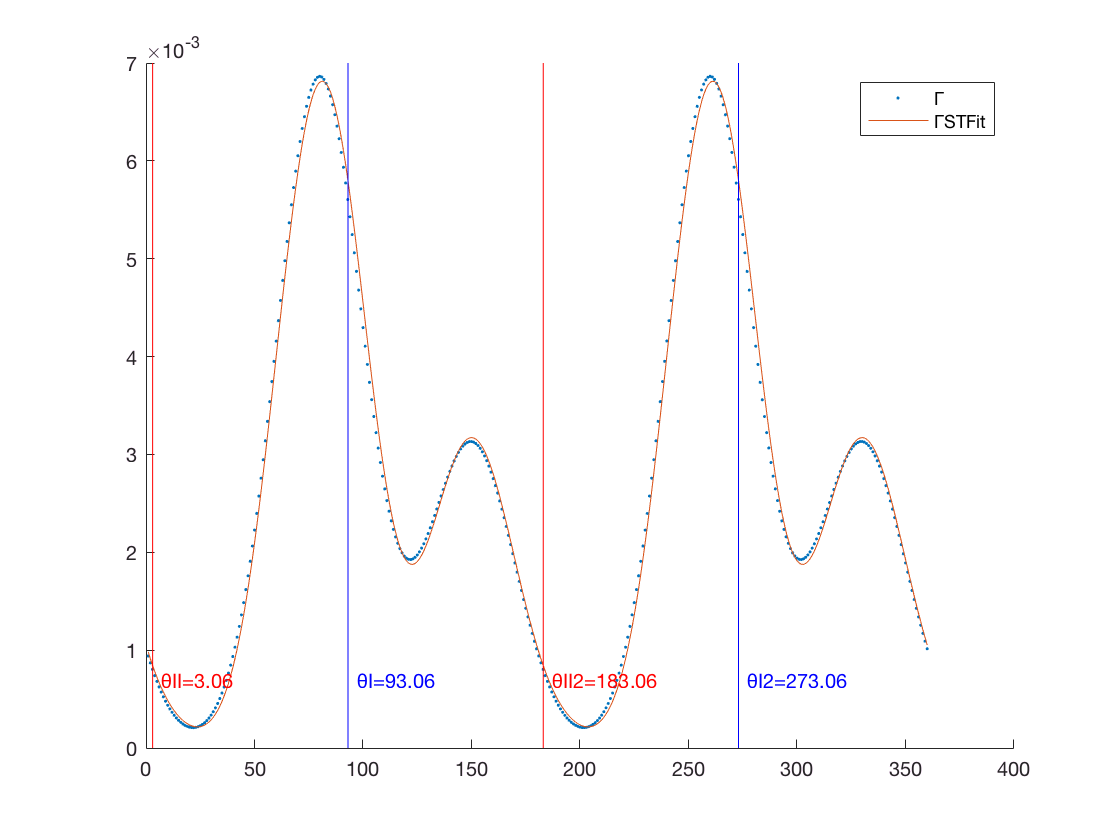

figure
hold on
plot(1:360,gamma,'.');plot(1:360,gamma_STFit); 
vline(theta1,'b', sprintf('θI=%.2f',theta1)); vline(theta1+180,'b', sprintf('θI2=%.2f',theta1+180)); 
vline(theta2,'r', sprintf('θII=%.2f',theta2)); vline(theta2+180,'r', sprintf('θII2=%.2f',theta2+180)); 
legend('show','Γ','ΓSTFit')
hold off

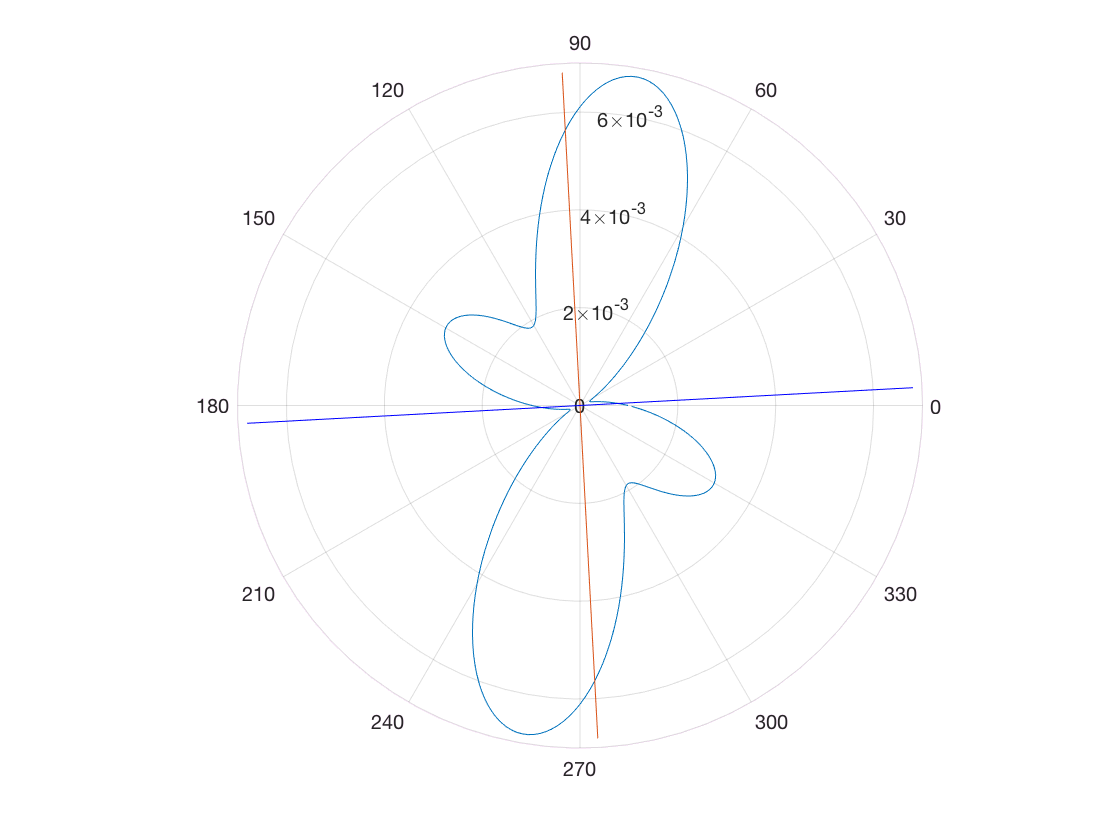


figure
polarplot(0:pi/180:(2*pi-pi/180), gamma_STFit)
hold on
rho=[-max(gamma_STFit) max(gamma_STFit)];
theta=[theta1*pi/180 theta1*pi/180];
polarplot(theta,rho);
theta=[theta2*pi/180 theta2*pi/180];
polarplot(theta,rho,'b');
hold off

**PI segment stats**

piSeg = theta2:1:(theta2+180);
gamma_Ffit_pi = evalFourier(an, bn, 2, piSeg);
gamma_Ffit_pi=gamma_Ffit_pi/sum(gamma_Ffit_pi); %% This is weird
% mean = compute_mean(gamma_Ffit_pi, piSeg);
dp = data_point

dp =   data_point with properties:

    intensity_data: []
                 x: []
                 y: []
                an: []
                bn: []
           raw_odf: []
               odf: []
                 D: []
          mean_raw: []
          mean_rep: []
            oi_raw: []
            oi_rep: []
        corr_coeff: []
         r_squared: []


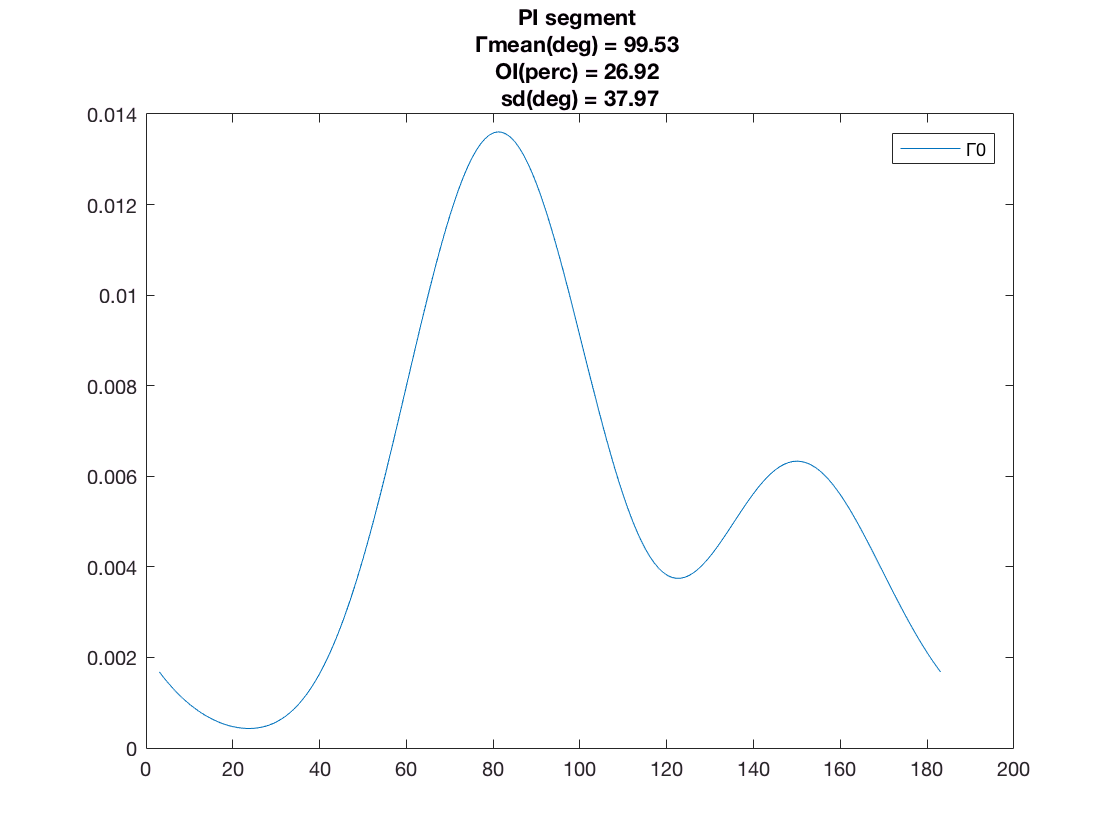

dp.an = an;
dp.bn = bn;
dp.odf = gamma_Ffit;
mean = compute_mean(gamma_Ffit_pi, piSeg);
var = compute_var(gamma_Ffit_pi, piSeg, mean);
sd = sqrt(var);
syms x
sdMax = double(sqrt((1/180) * int(x^2, x, -90, 90)));
OI = 100*(1-sd/sdMax);

figure
plot(piSeg,gamma_Ffit_pi)
legend('show','Γ0','ΓFfit'); title(sprintf('PI segment \nΓmean(deg) = %.2f \nOI(perc) = %.2f \nsd(deg) = %.2f',mean,OI,sd));

**Compute Tensors in new Coordinate system**

thetaR = 45;
Q = [cosd(thetaR) sind(thetaR); -sind(thetaR) cosd(thetaR)];
for i = 1:length(D)
    D_R{i} = rotateTensor(D{i}, i*2, Q);
end
gamma_STFitR = evalGammaST(D_R,1:360);
gamma_STFitR = gamma_STFitR/sum(gamma_STFitR);

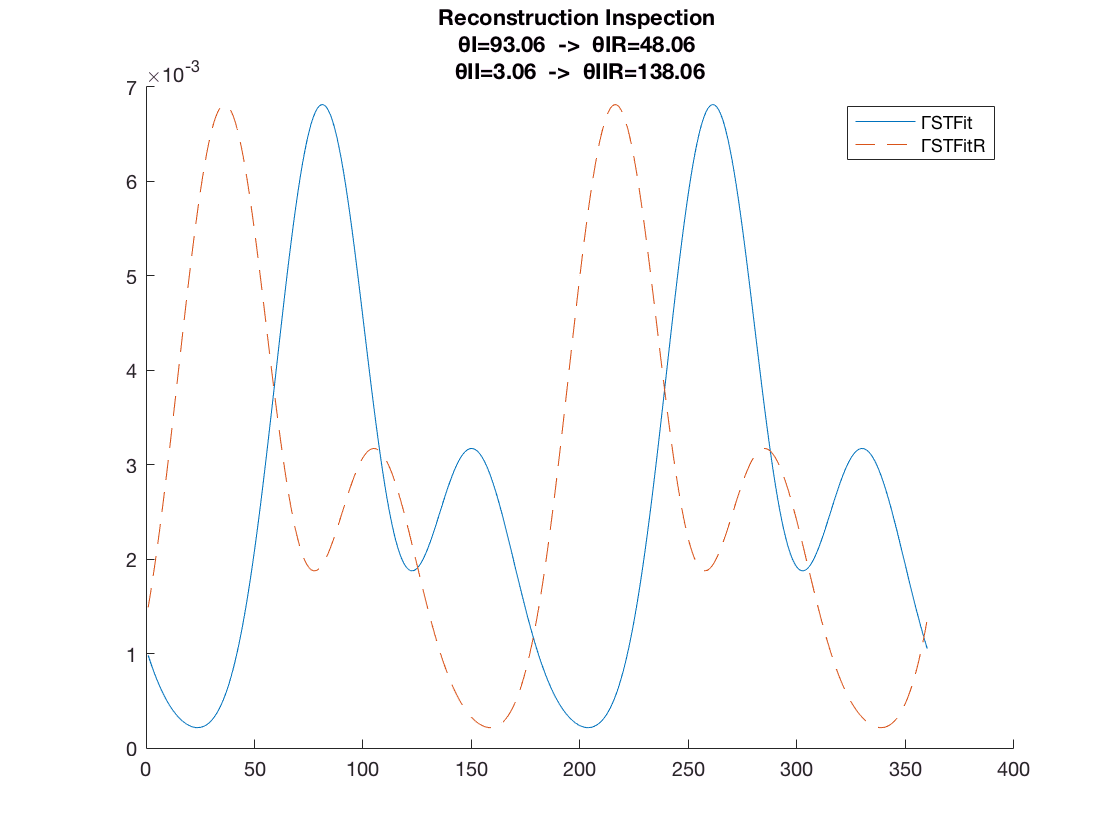

D_ij = D_R{1};  
[v, d] = eig(D_ij);
theta1R = atan(v(2,1)/v(1,1)) * (180/pi) + 90;
theta2R = atan(v(2,2)/v(1,2)) * (180/pi) + 90;

figure
hold on
plot(1:360,gamma_STFit)
plot(1:360,gamma_STFitR,'--')
legend('show','ΓSTFit','ΓSTFitR')
title(sprintf('Reconstruction Inspection \nθI=%.2f  ->  θIR=%.2f \nθII=%.2f  ->  θIIR=%.2f',theta1, theta1R, theta2, theta2R));
hold off

**Fourier Series check of rotated \Gamma**

coeffs_R = ComputeCoefficientsFromTensors(D_R);

an = coeffs_R(1:2:length(coeffs_R));
bn = coeffs_R(2:2:length(coeffs_R));

gamma_Ffit_R = evalFourier(an,bn,1,1:360);
gamma_Ffit_R = gamma_Ffit_R/sum(gamma_Ffit_R);

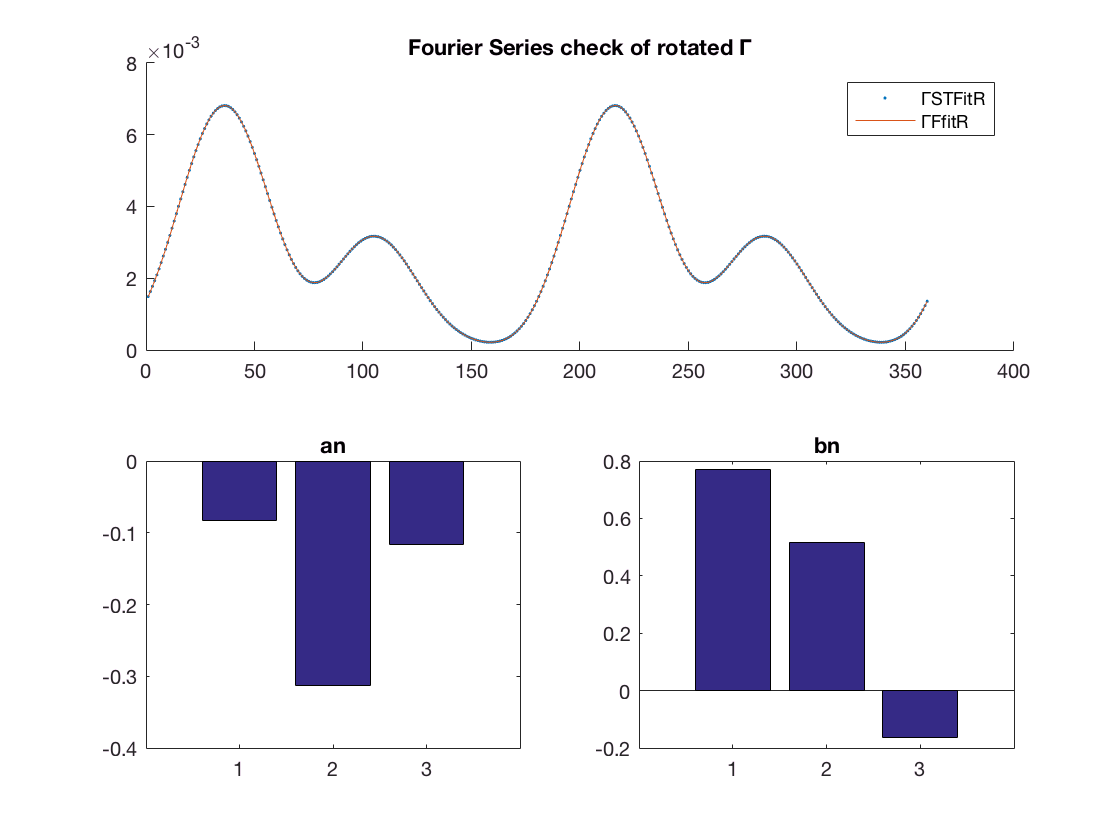

figure 
subplot(2,2,1:2) 
hold on
plot(1:360,gamma_STFitR,'.') 
plot(1:360,gamma_Ffit_R)
legend('show','ΓSTFitR','ΓFfitR'); title('Fourier Series check of rotated Γ');
hold off

subplot(2,2,3); bar(an); title('an');
subplot(2,2,4); bar(bn); title('bn');

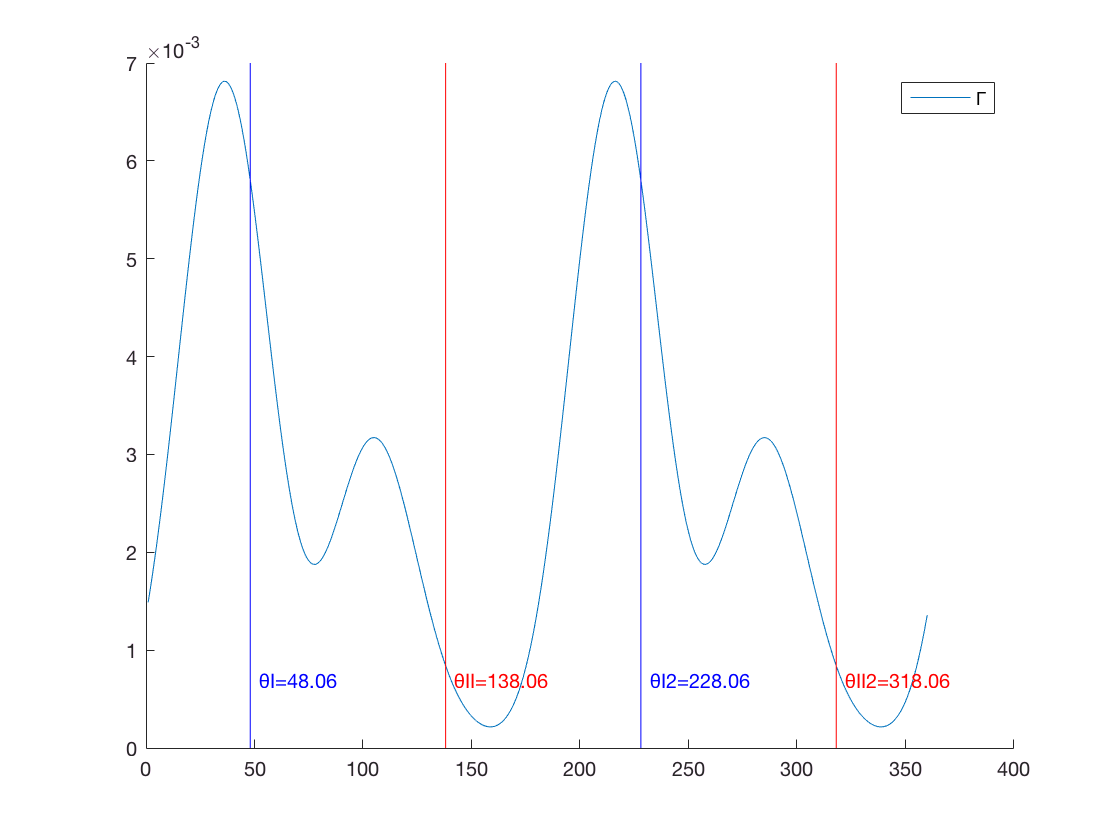

figure
hold on
plot(1:360,gamma_STFitR); 
vline(theta1R,'b', sprintf('θI=%.2f',theta1R)); vline(theta1R+180,'b', sprintf('θI2=%.2f',theta1R+180)); 
vline(theta2R,'r', sprintf('θII=%.2f',theta2R)); vline(theta2R+180,'r', sprintf('θII2=%.2f',theta2R+180)); 
legend('show','Γ','ΓSTFitR')
hold off

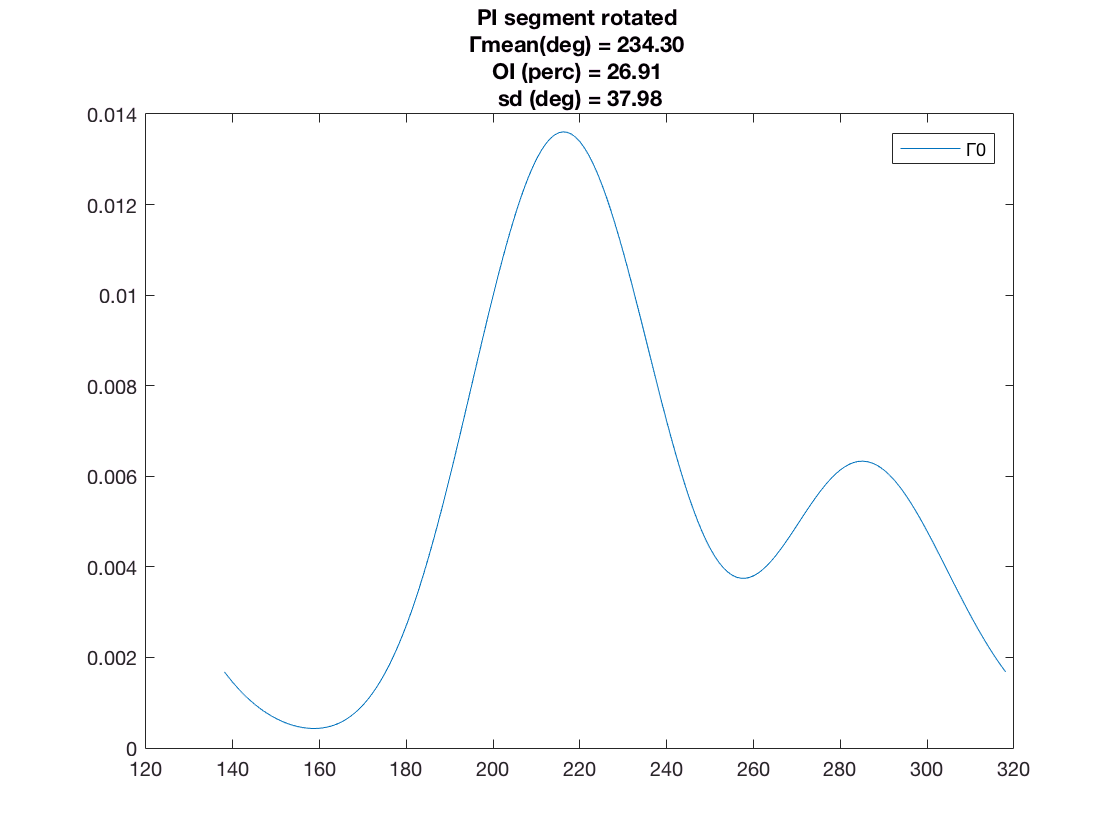

piSeg = theta2R:1:(theta2R+180);
gamma_Ffit_pi_R = evalFourier(an, bn, 2, piSeg);
gamma_Ffit_pi_R=gamma_Ffit_pi_R/sum(gamma_Ffit_pi_R); %% This is weird

mean = compute_mean(gamma_Ffit_pi_R, piSeg);
var = compute_var(gamma_Ffit_pi_R, piSeg, mean);
sd = sqrt(var);
syms x
sdMax = double(sqrt((1/180) * int(x^2, x, -90, 90)));
OI = 100*(1-sd/sdMax);

figure
plot(piSeg,gamma_Ffit_pi_R)
legend('show','Γ0','ΓFfit'); title(sprintf('PI segment rotated \nΓmean(deg) = %.2f \nOI (perc) = %.2f \nsd (deg) = %.2f',mean,OI,sd));